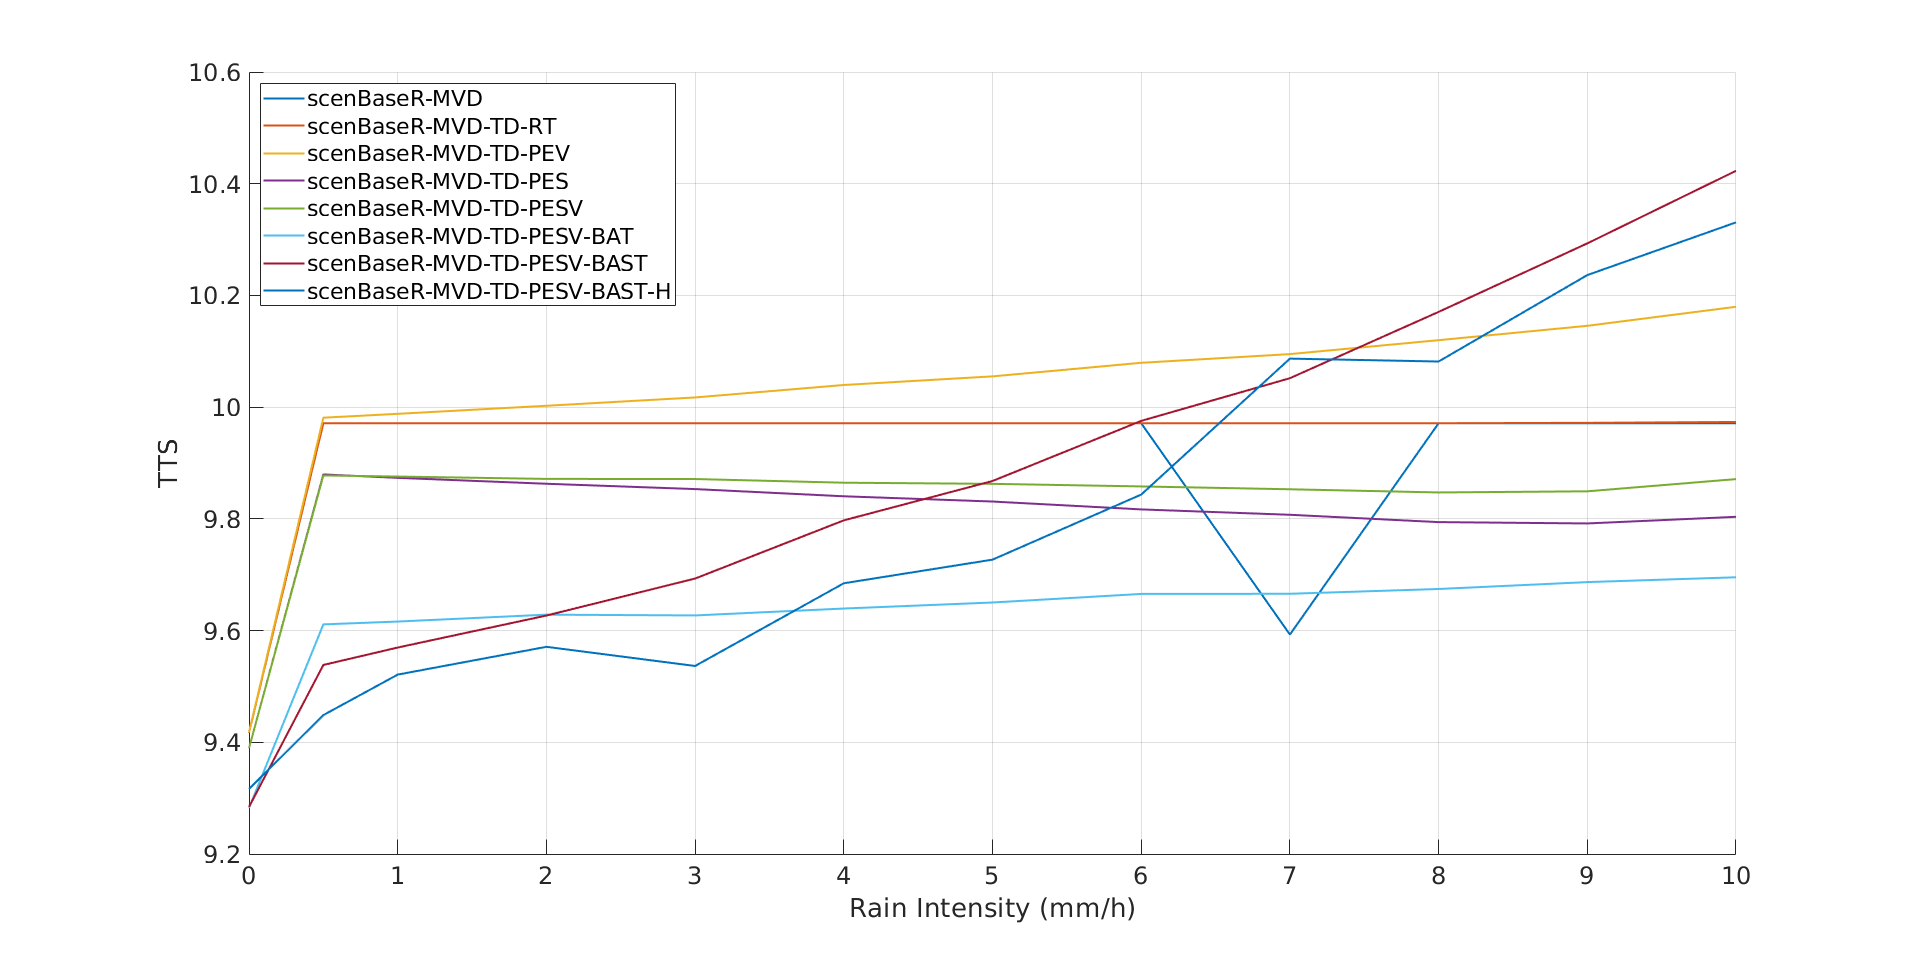

mineKPI = struct;
% TITLES FOR FIGURES
intensity = [0,0.5,1,2,3,4,5,6,7,8,9,10];
titles = { ...
    'I=0.0', ...              
    'I=0.5', ...                
    'I=1.0', ...              
    'I=2.0', ...                
    'I=3.0', ...          
    'I=4.0', ...              
    'I=5.0', ...                
    'I=6.0', ...
    'I=7.0', ...              
    'I=8.0', ...                
    'I=9.0', ...
    'I=10.0'
    };
% NAMES OF SCENARIOS
scenarios = { ...
       'scenBaseR_MVD',...
       'scenBaseR_MVD_TD_RT'...
       'scenBaseR_MVD_TD_PEV'...
       'scenBaseR_MVD_TD_PES'...
       'scenBaseR_MVD_TD_PESV'...
       'scenBaseR_MVD_TD_PESV_BAT'...
       'scenBaseR_MVD_TD_PESV_BAST'...
       'scenBaseR_MVD_TD_PESV_BAST_H'...    
    };

itau = 'tau=00';

for ri = 1: numel(titles)
     for  s = 1:numel(scenarios)
        fname = sprintf('%s_%s_%s.mat',scenarios{s}, titles{ri}, itau);
        load(fname,'Sim');
        
          %save the data in fields
          tbl(ri,s) = Sim.Edie.TTS;
          tblsp(ri,s) =  Sim.Edie.u;
          tblnc(ri,s) = Sim.numCollisions;
%         mineKPI = setfield(mineKPI, fname, 'speed', {iscenario}, Sim.Edie.u);
%         mineKPI = setfield(mineKPI, fname, 'TTS'  , {iscenario}, Sim.Edie.TTS);
%         mineKPI = setfield(mineKPI, fname, 'NoA'  , {iscenario}, Sim.numCollisions);
     end
end
figure('Renderer', 'painters', 'Position', [10 10 2048 1024],'DefaultAxesFontSize',18);
hold on;
grid on;
for i =1:8
    plot(intensity,tbl(:,i),'LineWidth',1.5);
end
leg = { ...
       'scenBaseR-MVD',...
       'scenBaseR-MVD-TD-RT'...
       'scenBaseR-MVD-TD-PEV'...
       'scenBaseR-MVD-TD-PES'...
       'scenBaseR-MVD-TD-PESV'...
       'scenBaseR-MVD-TD-PESV-BAT'...
       'scenBaseR-MVD-TD-PESV-BAST'...
       'scenBaseR-MVD-TD-PESV-BAST-H'...    
    };
legend(leg,'Location','northwest');
xlabel('Rain Intensity (mm/h)');
ylabel('TTS');

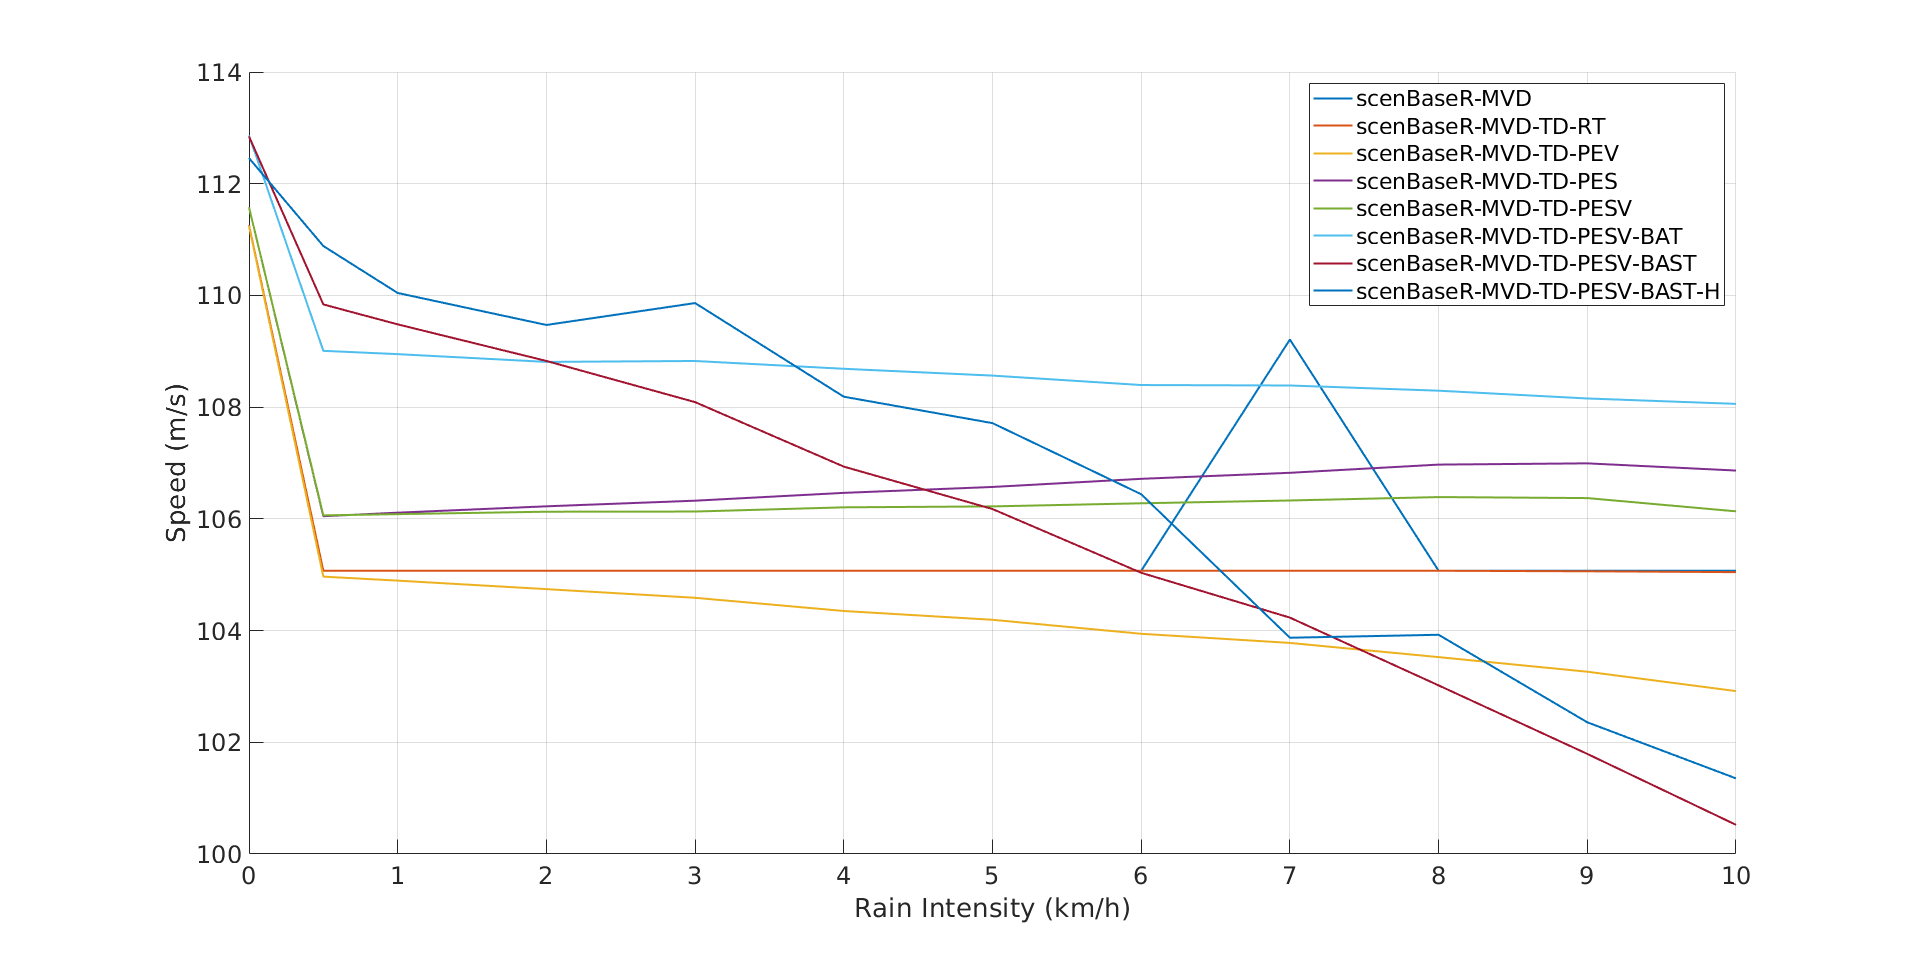


%speed kpi
figure('Renderer', 'painters', 'Position', [10 10 2048 1024],'DefaultAxesFontSize',18);
hold on;
grid on;
for i =1:8
    plot(intensity,tblsp(:,i),'LineWidth',1.5);
end
leg = { ...
       'scenBaseR-MVD',...
       'scenBaseR-MVD-TD-RT'...
       'scenBaseR-MVD-TD-PEV'...
       'scenBaseR-MVD-TD-PES'...
       'scenBaseR-MVD-TD-PESV'...
       'scenBaseR-MVD-TD-PESV-BAT'...
       'scenBaseR-MVD-TD-PESV-BAST'...
       'scenBaseR-MVD-TD-PESV-BAST-H'...    
    };
legend(leg,'Location','northeast');
xlabel('Rain Intensity (mm/h)');
ylabel('Speed (km/h)');

%FOG

% NAMES OF SCENARIOS MODERATE
scenariosM = { ...
       'scenarioModerate_TD_RT',...
       'scenarioModerate_TD_RT_PEV'...
       'scenarioModerate_TD_RT_PES'...
       'scenarioModerate_TD_RT_PESV'...
       'scenarioModerate_TD_RT_PESV_BAS'...
       'scenarioModerate_TD_RT_PESV_BAS_H_02'...    
    };


     for  s = 1:numel(scenarios)
        fname = sprintf('%s_%s.mat',scenariosM{s}, itau);
        load(fname,'Sim');
        
          %save the data in fields
          tblTTSfog(1,s) = Sim.Edie.TTS;
          tblSPFog(1,s) =  Sim.Edie.u;
     end
     % NAMES OF SCENARIOS LOW
scenariosL = { ...
       'scenarioLow_TD_RT',...
       'scenarioLow_TD_RT_PEV'...
       'scenarioLow_TD_RT_PES'...
       'scenarioLow_TD_RT_PESV'...
       'scenarioLow_TD_RT_PESV_BAS'...
       'scenarioLow_TD_RT_PESV_BAS_H_02'...    
    };


     for  s = 1:numel(scenarios)
        fname = sprintf('%s_%s.mat',scenariosL{s}, itau);
        load(fname,'Sim');
        
          %save the data in fields
          tblTTSfogL(1,s) = Sim.Edie.TTS;
          tblSPFogL(1,s) =  Sim.Edie.u;
     end





